%storing vatiables for processing
imgPix=400;
dt=2*1e-6;
fc=50000;
ta=1.0e-4;
ns=50;
%received(10:20)

%creating time samples
%m=2*received-1;
m=received;
t = dt:dt:dt*size(m,2);
%stem(received);
%plot(t,m);
%size(t)
%size(received,2)

% multiplying modulated signal by cos(2*pi*fc*t)
sig1 = m .* cos(2*pi*fc*t);

% multiplying modulated signal by sin(2*pi*fc*t)
sig2 = m .* sin(2*pi*fc*t);

%plot(t,sig1);

% now we will apply the filter (conv):
%floor(ta/dt)
sig1 = conv(sig1,dt*ones(1, floor(ta/dt)), 'same');
sig2 = conv(sig2, dt*ones(1, floor(ta/dt)), 'same');

%plot(t,sig1);

% threshold as before
sig1 = sig1 > 0;
sig2 = sig2 > 0;
%size(sig1)
%plot(t(1:30000), sig1(1:30000));%

%sampling times at which value will be taken into account
%disp(sig1)
%size(received,2)
%ta*(400*400)
%dt*size(received,2)
%sampling_times = ta/2:ta:ta*(400*400);%total bits in signal,ta*(400*400/2)
%size(sampling_times)
%sampling_times = ns/2:ns:ns*(imgPix*imgPix);
%size(sampling_times)
sampling_times = ta/2:ta:dt*size(received,2);%total bits in signal,ta*(400*400/2)
sampling_index=floor(sampling_times/dt);


m1_reconstructed = sig1(sampling_index);

m1_reconstructed = m1_reconstructed > 0;

m2_reconstructed = sig2(floor(sampling_times/dt));
m2_reconstructed = m2_reconstructed >0;


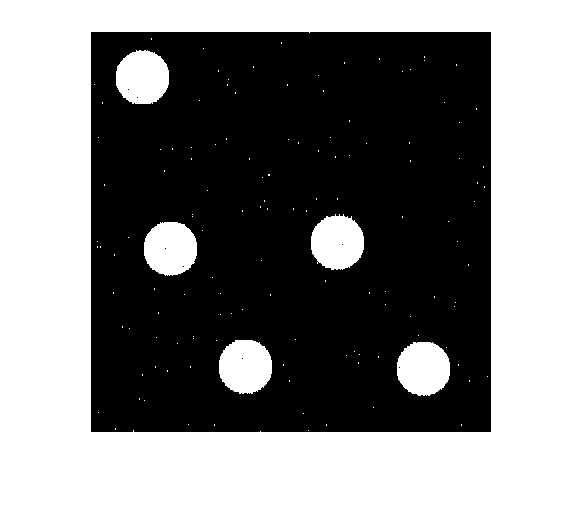

% combining them,
% odd places
m_reconstructed_1 = [ m2_reconstructed ; m1_reconstructed]; 
% even places
m_reconstructed_2 = [ m1_reconstructed ; m2_reconstructed]; 

m_final_1 = m_reconstructed_1(:);
m_final_2 = m_reconstructed_2(:);
%size(m_final_1)
%making the 1D matrix to 2D ro use it as an image,we know that the bits will be written in columnwise manner
img1=reshape(m_final_1(:),400,400);
img2=reshape(m_final_2(:),400,400);
imshow(img1)

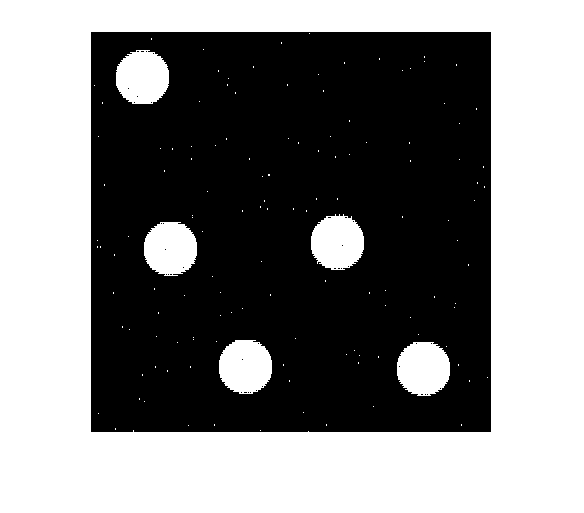

imshow(img2)

%image processing to remove some noise
morphBW = bwmorph(img1,'clean');
morphBW = bwmorph(morphBW,'open');
morphBW = bwmorph(morphBW,'clean');
%morphBW = bwmorph(morphBW,'erode');
%morphBW = bwmorph(morphBW,'erode');
%morphBW = bwmorph(morphBW,'dilate');
%morphBW = bwmorph(morphBW,'dilate');
imshow(morphBW)


CC=bwconncomp(morphBW,8)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [400 400]
      NumObjects: 5
    PixelIdxList: {[2290×1 double]  [2290×1 double]  [2298×1 double]  [2294×1 double]  [2293×1 double]}


%CC.Connectivity

S = regionprops(CC,'Centroid')

S = 5×1 struct array with fields:
    Centroid


S.Centroid

ans =    52.0694   46.0712


ans =    80.0096  217.0694


ans =   154.9848  335.0065


ans =   246.9952  211.0418


ans =   333.0379  337.0597
